## Download Data

%Download and extract the dataset
url = "https://data.mendeley.com/public-files/datasets/cp3473x7xv/files/ad7ac5c9-2b9e-458a-a91f-6f3da449bdfb/file_downloaded";
downloadFolder = tempdir;
outputFolder = fullfile(downloadFolder, "LGHG2@n10C_to_25degC");

if ~exist(outputFolder, "dir")
    fprintf("Downloading zip file")
    filename = fullfile(downloadFolder, "LGHG2@n10C_to_25degC.zip");
    websave(filename, url);
    unzip(filename, outputFolder)
end

## Prepare Training, Test and Validation Data

trainingData = fullfile(outputFolder, "Train"); %Returns character vector with full path to the file
fdsTrain = fileDatastore(trainingData, ReadFcn=@load); %FileDatastore object manages large collections of files
dsTrain = transform(fdsTrain, @(data) {data.X, data.Y}); %Predictor Data = X & Target Data = Y returned by dsTrain
preview(dsTrain) %Preview transformed datastore 1.1 = predictor and 1.2 = target

ans = 1×2 cell array
    {5×669956 double}    {1×669956 double}


testData = fullfile(outputFolder, "Test");
fdsTest = fileDatastore(testData, ReadFcn=@load);
tdsPredictorsTest = transform(fdsTest, @(data) {data.X});
preview(tdsPredictorsTest)

ans = 1×1 cell array
    {5×39293 double}


tdsTargetTest = transform(fdsTest,@(data) {data.Y});
preview(tdsTargetTest)

ans = 1×1 cell array
    {[1 1.0000 1.0000 1.0000 1.0000 1.0000 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9998 0.9998 0.9998 0.9998 0.9998 0.9998 0.9997 0.9996 0.9994 0.9991 0.9989 0.9988 0.9987 0.9983 0.9982 0.9980 0.9980 0.9980 0.9980 0.9981 0.9981 0.9981 0.9981 0.9981 0.9981 0.9980 0.9980 0.9979 0.9978 0.9975 0.9972 0.9970 0.9969 0.9969 0.9969 0.9970 0.9970 0.9970 0.9970 0.9970 0.9968 0.9965 0.9962 0.9960 0.9958 0.9957 0.9956 0.9956 0.9956 0.9955 0.9954 0.9954 0.9954 0.9953 0.9953 0.9952 0.9950 0.9950 0.9950 0.9950 0.9949 0.9948 0.9947 0.9946 0.9946 0.9945 0.9944 0.9942 0.9939 0.9938 0.9936 0.9935 0.9934 0.9933 0.9932 0.9932 0.9931 0.9931 0.9930 0.9929 0.9929 0.9929 0.9929 0.9928 0.9926 0.9925 0.9924 0.9923 0.9923 0.9923 0.9923 0.9923 0.9921 0.9920 0.9918 0.9917 0.9915 0.9914 0.9914 0.9914 0.9915 0.9915 0.9916 0.9916 0.9916 0.9917 0.9917 0.9918 0.9918 0.9918 0.9918 0.9918 0.9918 0.9918 0.9918 0.9917 0.9917 0.9917 0.9917 0.9917 0.9917 0.9917 0.991

indices = 1;
fdsVal = subset(fdsTest, indices);
dsVal = transform(fdsVal,@(data) {data.X, data.Y});

## Define Network Architecture

%Set the number of inputs features to five (voltage, current, temperature, average voltage, and average current).
numFeatures = 5;
numResponses = 1; %Set the number of output features to one (SOC).
numHiddenNeurons = 55; %Specify the number of hidden neurons.

%Define the neural network architecture
layers = [
    sequenceInputLayer(numFeatures, Normalization="zerocenter")  %Input Layer to model; normalized by subtracting mean of each feature | center at 0.
    fullyConnectedLayer(numHiddenNeurons)   %Computer linear combinations of inputs with bias term | dimensionality determined by # of neurons
    tanhLayer                               %Hyperbolic tangent activation function to outputs of previous layer | Introduces non-linearity | stabilize gradients
    fullyConnectedLayer(numHiddenNeurons)
    leakyReluLayer(0.3)                     %Rectified Linear Unit activation function | 0.3 = slope of (-) part of function | Improves gradient flow
    fullyConnectedLayer(numResponses)       %Connects learned features to output
    clippedReluLayer(1)                     %Activation function | non-linearity
];

options = trainingOptions("adam", ...
    InputDataFormats = "CTB", ...
    MaxEpochs = 1200, ...                       %1200 epochs with mini-batches of size 1 using "adam" solver
    SequencePaddingDirection = "left", ...      %Specify padding direction onto a batch | "pre-padding" = left
    Shuffle = "every-epoch", ...
    GradientThreshold = 1, ...                  %To prevent gradiennts from exploding, setting a threshold
    InitialLearnRate = 0.01, ...                %How fast model will learn; smaller value = slower learning | larger value = can cause overshooting
    LearnRateSchedule = "piecewise", ...        %'piecewise' allows learning rate to decrease during training to help mdl converge more effectively
    LearnRateDropPeriod = 400, ...              %Rate at which learning rate will be reduced
    LearnRateDropFactor = 0.1, ...              % 0.1 = 10 epochs meaning after this learning rate will be multiplied by 0.1 (reduced by 90%)
    ValidationData = dsVal, ...
    ValidationFrequency = 30, ...               %Every 30 epochs - validate
    MiniBatchSize = 1, ...                      %Model will update its weights after processing 1 sample
    Plots = "training-progress", ...
    Metrics = "rmse", ...
    Verbose = 0);                               %Plot training information

## Train the Network

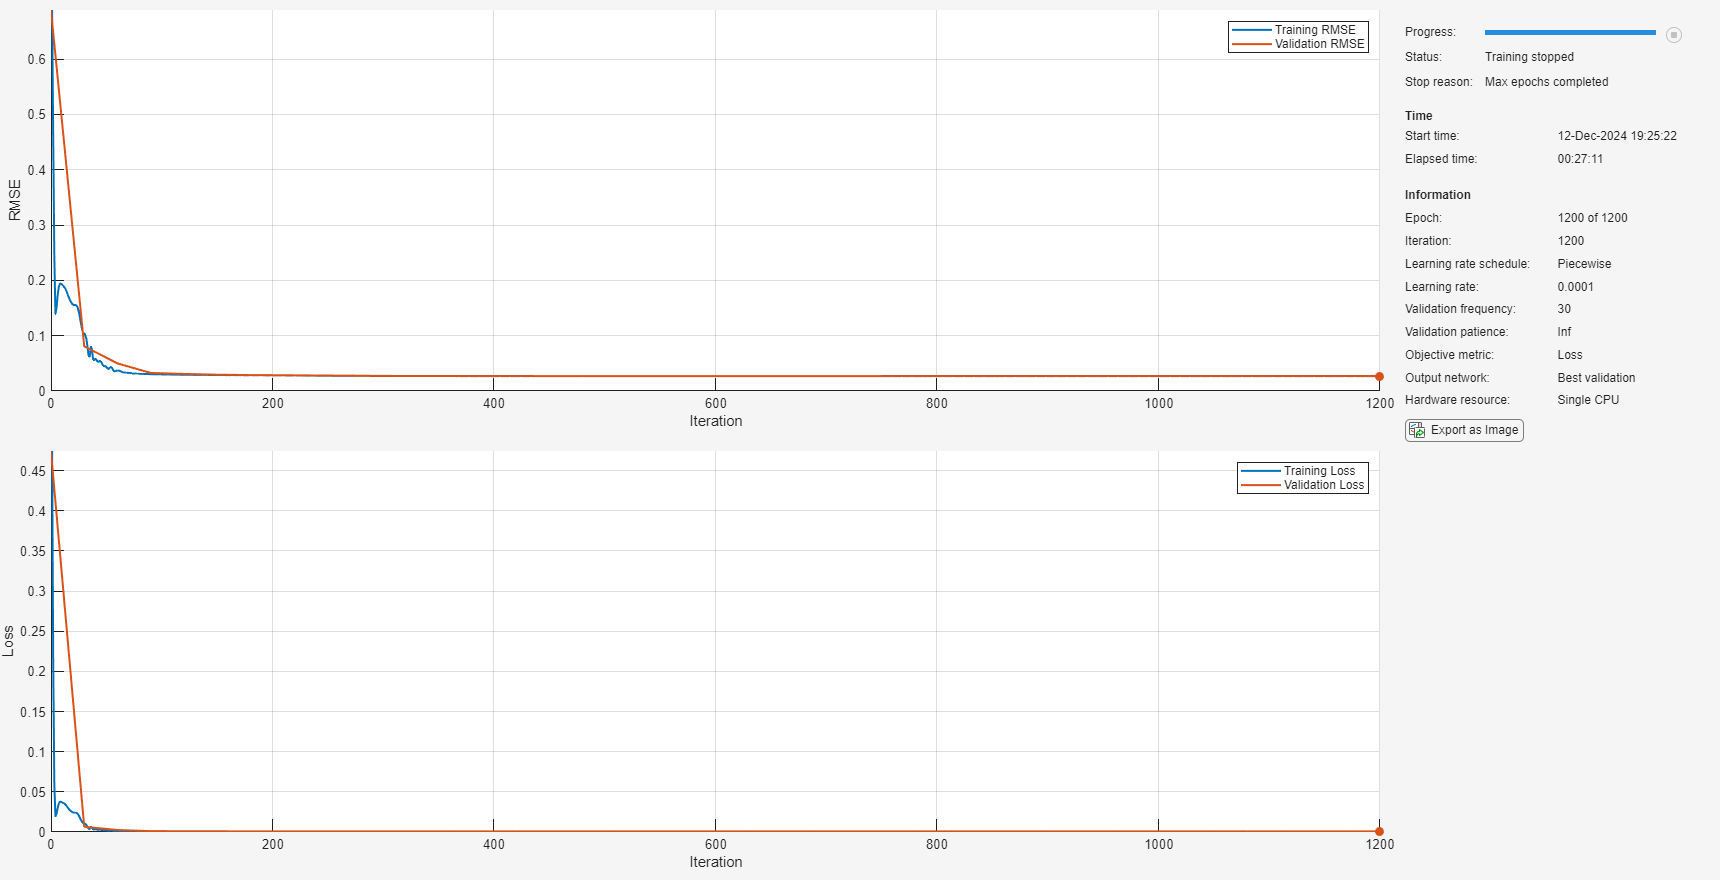

net = trainnet(dsTrain, layers, "mse", options);

## Test the Network

YPred = minibatchpredict(net,tdsPredictorsTest,InputDataFormats="CTB",MiniBatchSize=1,UniformOutput=false); %Input data format "CTB" (channel, time, batch)
YTarget = readall(tdsTargetTest);  %Compare SOC predictions by network to target SOC from test data

Unrecognized function or variable 'tdsTargetsTest'.

figure

%Plot predicted and target SOC for different ambient temperatures
nexttile
plot(YPred{1})
hold on
plot(YTarget{1})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("n10degC")

nexttile
plot(YPred{2})
hold on
plot(YTarget{2})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("0degC")

nexttile
plot(YPred{3})
hold on
plot(YTarget{3})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("10degC")

nexttile
plot(YPred{4})
hold on
plot(YTarget{4})
legend(["Predicted" "Target"],Location="Best")
ylabel("SOC")
xlabel("Time(s)")
title("25degC")

%Calculate the error between predicted & target SOC for each temperature
Err_n10degC = YPred{1} - YTarget{1};
Err_0degC = YPred{2} - YTarget{2};
Err_10degC = YPred{3} - YTarget{3};
Err_25degC = YPred{4} - YTarget{4};

%Calculate the RMSE between predicted & target SOC for each temperature
RMSE_n10degC = sqrt(mean(Err_n10degC.^2))*100;
RMSE_0degC = sqrt(mean(Err_0degC.^2))*100;
RMSE_10degC = sqrt(mean(Err_10degC.^2))*100;
RMSE_25degC = sqrt(mean(Err_25degC.^2))*100;

%Calculate the max error between predicted & target SOC for each temperature
MAX_n10degC = max(abs(Err_n10degC))*100;
MAX_0degC = max(abs(Err_0degC))*100;
MAX_10degC = max(abs(Err_10degC))*100;
MAX_25degC = max(abs(Err_25degC))*100;

%Plot the RMSE for each temperature
temp = [-10,0,10,25];
figure
nexttile
bar(temp,[RMSE_n10degC,RMSE_0degC,RMSE_10degC,RMSE_25degC])
ylabel("RMSE (%)")
xlabel("Temperature (C)")

%Plot maximum absolute error for different temperatures
nexttile
bar(temp,[MAX_n10degC,MAX_0degC,MAX_10degC,MAX_25degC])
ylabel("MAX (%)")
xlabel("Temperature (C)")

%Results:
% Lowers values in the RMSE and MAX plots indicate more accurate
% predictions for the corresponding temperatures. Larger values in the same
% plots indicate less accuracte predictions for the corresponding
% temperatures.